Load Dataset

dataFolder = "..\..\PointClouds";
labelFolder = "..\..\Masks";
addpath(genpath(dataFolder))
addpath(genpath(labelFolder))

pcds = fileDatastore(dataFolder,"ReadFcn",@(x) pcread(x),'IncludeSubfolders',true);

classNames = ["unlabelled"
    "ATV"
    "JeepGreen"
    "PickupWhite"
    "SUVBlack"
    "VanWhite"
    "Plane"
    "SedanBlack"
    "SportsCarYellow"];

numClasses = numel(classNames);
labelIDs = 1 : numClasses;

pxds = pixelLabelDatastore(labelFolder,classNames,labelIDs, "IncludeSubfolders",true);

Use the `combine `function to combine the point clouds and labels into a single datastore for training. Then, separate the data into training, validation, and test data. 

cds = combine(pcds,pxds);
skipFrame = 100;
numImages = cds.numpartitions;
Indices = 1:skipFrame:numImages;
numIndices = length(Indices);
shuffleOrder = randperm(numIndices);
shuffledIndices = Indices(shuffleOrder);
numTrain = floor(0.8*numIndices);
numVal = ceil(0.1*numIndices);

cdsTrain = subset(cds,shuffledIndices(1:numTrain));
cdsVal = subset(cds,shuffledIndices(numTrain+1:numTrain+numVal));
cdsTest = subset(cds,shuffledIndices(numTrain+numVal+1:end));

Verify ground truth masks

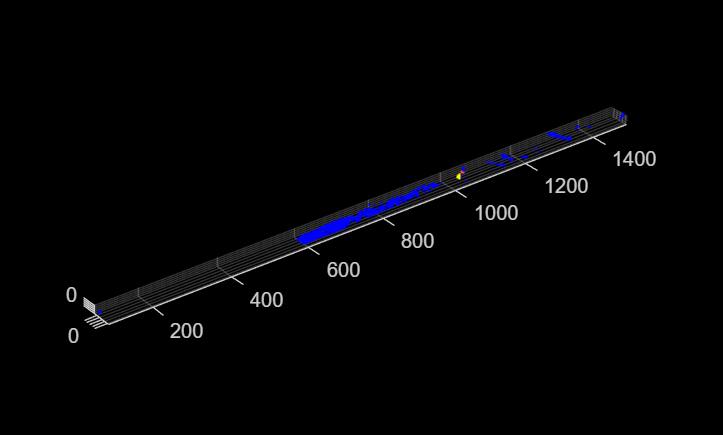

% reset(cdsTrain)
trainCell = read(cdsTrain);
trainPC = trainCell{1};
trainMask = single(trainCell{2});
trainMask(trainMask==0) = NaN;
% cmap = jet()numClasses
ax = pcshow(trainPC.Location,trainMask);

% helperLabelColorbar(ax,classNames)
function helperLabelColorbar(ax,classNames)
% The helperLabelColorbar function adds a colorbar to the current axis. The
% colorbar is formatted to display the class names with the color.
%
% This is an example helper function that is subject to change or removal
% in future releases.

% Copyright 2024 MathWorks, Inc.

% Colormap for the original classes.
numClasses = numel(classNames);

% Get the turbo colormap array.
cmap = turbo(numClasses); 

% Apply the colormap to the specified axes.
colormap(ax,cmap);

% Add colorbar to the current figure.
c = colorbar(ax);
c.Color = "white";

% Center tick labels and use class names for tick marks.
c.Ticks = 1:1:numClasses;
c.TickLabels = classNames;

% Remove tick mark.
c.TickLength = 0;
end
% figure;
% % colorMask = reshape(cmap(trainMask,:), [128, 128, 3]);
% pcshow(trainPC.Location, trainMask);
% title("Ground Truth")
% colormap(jet(numClasses))
% colorbar('Ticks', 1:1:numClasses, 'TickLabels', classNames); % Add colorbar with class names
% % Rotate the axes to show the YZ plane
% ax = gca; % Get current axes
% view(ax, [-90, 0]); % Set view to YZ plane

Use the randlanet function to create a RandLANet segmentation network.

% net = randlanet("pandaset",classNames, NumPoints=16384); % Transfer Learning
net = randlanet("none",classNames,GridStep = 0.1, NumPoints=16384, PointProperty="intensity");

Use the Adam optimization algorithm to train the network. Use the `trainingOptions `function to specify the hyperparameters.

learningRate = 0.001;
numEpochs = 10;
miniBatchSize = 20;
learnRateDropFactor = 0.9;
executionEnvironment = "auto";
preprocessEnvironment = "serial"; %parallel

options = trainingOptions("adam", ...
    InitialLearnRate = learningRate, ...
    MaxEpochs = numEpochs, ...
    MiniBatchSize = miniBatchSize, ...
    LearnRateSchedule = "piecewise", ...
    LearnRateDropPeriod = 1,...
    LearnRateDropFactor = learnRateDropFactor, ...
    Plots = "training-progress", ...
    ExecutionEnvironment = executionEnvironment, ...
    PreprocessingEnvironment = preprocessEnvironment, ...
    ResetInputNormalization = false, ...
    CheckpointFrequencyUnit = "epoch", ...
    CheckpointFrequency = 1, ...
    CheckpointPath = tempdir, ...
    BatchNormalizationStatistics="moving",...
    verbose = true, ...
    ValidationData = cdsVal, ...
    ValidationFrequency = 500);

Use the trainRandlanet function to train the RandLANet segmentation network, set the `doTraining` argument to `true`. Otherwise, load a pretrained segmentation network.

doTraining = false;

if doTraining
    trainedNet = trainRandlanet(cdsTrain,net,options);
    modelName = "trainedRandLANet_None_" +string(datetime)+ ".mat";
    save(modelName, "trainedNet");
else
    load("trainedRandLANet_Riccardo_Pandaset_v1.mat");
end

Test trained model on the Test datastore

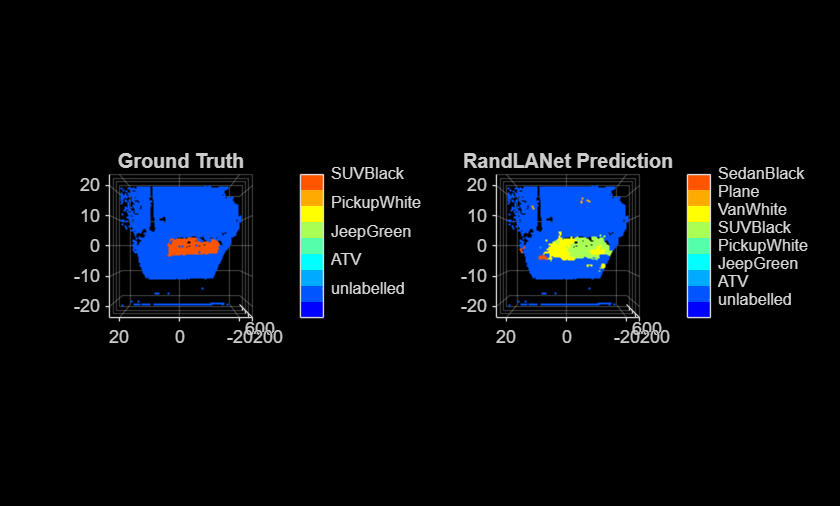

tiledlayout(1,2)
while hasdata(cdsTest)
    % Read a single point cloud and segment it using the trained model
    testCell = read(cdsTest);
    testPC = testCell{1};
    testMask = uint8(testCell{2});

    testPred = uint8(segmentObjects(trainedNet,testPC)); %uint8?

    nexttile(1) % try 2 pcviewer in the same tiledlayout? no need for adding cuboids
    pcshow(testPC.Location, testMask);
    title("Ground Truth")
    colormap(jet(numClasses)); % Set colormap based on number of classes
    colorbar('Ticks', 1:numClasses, 'TickLabels', classNames); % Add colorbar with class names
    % Rotate the axes to show the YZ plane
    ax = gca; % Get current axes
    view(ax, [-90, 0]); % Set view to YZ plane

    nexttile(2)
    pcshow(testPC.Location, testPred);
    title("RandLANet Prediction")
    colormap(jet(numClasses)); % Set colormap based on number of classes
    colorbar('Ticks', 1:numClasses, 'TickLabels', classNames); % Add colorbar with class names
    % Rotate the axes to show the YZ plane
    ax = gca; % Get current axes
    view(ax, [-90, 0]); % Set view to YZ plane
    drawnow; % Update the figure
end

% Test on the entire test datastore and evaluate the detector
testResults = segmentObjects(trainedNet,cdsTest.UnderlyingDatastores{1})


Running RandLANet network.
--------------------------
* Processed 62 point clouds.



testResults =   FileDatastore with properties:

                       Files: {
                              ' ...\SegmentObjectResults2\segmentObj_T3LiDAR_ATV_Site1_0660.mat';
                              ' ...\SegmentObjectResults2\segmentObj_T3LiDAR_ATV_Site1_0860.mat';
                              ' ...\SegmentObjectResults2\segmentObj_T3LiDAR_ATV_Site1_1360.mat'
                               ... and 59 more
                              }
                     Folders: {
                              ' ...\RandLANet_SemanticSegmentation\SegmentObjectResults2'
                              }
                 UniformRead: 0
                    ReadMode: 'file'
                   BlockSize: Inf
                  PreviewFcn: @(x)load(x).labels
      SupportedOutputFormats: ["txt"    "csv"    "dat"    "asc"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "ti

% testResultsT = transform(testResults,@(x) readResultsWithNaNs(x));
% testGroudTruthT = transform(cdsTest.UnderlyingDatastores{2},@(x) readResultsWithNaNs(x));
% metrics = evaluateSemanticSegmentation(testResultsT,testGroudTruthT)
testResultsT = transform(testResults,@(x) readResultsWithNaNs(x, classNames));
metrics = evaluateSemanticSegmentation(testResultsT,cdsTest)

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 62 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy     MeanIoU     WeightedIoU    MeanBFScore
    ______________    ____________    _________    ___________    ___________

      0.0084501         0.14871       0.0018888    0.00017345         NaN    



metrics =   semanticSegmentationMetrics with properties:

              ConfusionMatrix: [9×9 table]
    NormalizedConfusionMatrix: [9×9 table]
               DataSetMetrics: [1×5 table]
                 ClassMetrics: [9×3 table]
                 ImageMetrics: [62×5 table]


metrics.ClassMetrics
metrics.ConfusionMatrix

function [catOut] = readResultsWithNaNs(catIn, newcats)


catOut = setcats(catIn,newcats);

% if iscell(catIn)
%     catIn = catIn{:};
% end
% catOut  = categorical(uint8(catIn), 0:9);
end

% function helperLabelColorbar(ax,classNames)
% % The helperLabelColorbar function adds a colorbar to the current axis. The
% % colorbar is formatted to display the class names with the color.
% %
% % This is an example helper function that is subject to change or removal
% % in future releases.
% 
% % Copyright 2024 MathWorks, Inc.
% 
% % Colormap for the original classes.
% numClasses = numel(classNames);
% 
% % Get the turbo colormap array.
% cmap = turbo(numClasses); 
% 
% % Apply the colormap to the specified axes.
% colormap(ax,cmap);
% 
% % Add colorbar to the current figure.
% c = colorbar(ax);
% c.Color = "white";
% 
% % Center tick labels and use class names for tick marks.
% c.Ticks = 0:1:numClasses;
% c.TickLabels = classNames;
% 
% % Remove tick mark.
% c.TickLength = 0;
% end
